正在绘制 ORegan2022 模型的收敛图...


20
21
22
23
24
25
26
27
28
29
30
31
32
33
34
35
36
37
38
39
40
41
42
43
44
45
46
47
48
49
50
51
52
53
54
55
56
57
58
59
60
61
62
63
64
65
66
67
68
69
70
71
72
73
74
75
76
77
78
79
80
81
82
83
84
85
86
87
88
89
90
91
92
93
94
95
96
97
98
99
100
101
102
103
104
105
106
107
108
109
110
111
112
113
114
115
116
117
118
119
120
121
122
123
124
125
126
127
128
129
130
131
132
133
134
135
136
137
138
139
140
141
142
143
144
145
146
147
148
149
150
151
152
153
154
155
156
157
158
159
160
161
162
163
164
165
166
167
168
169
170
171
172
173
174
175
176
177
178
179
180
181
182
183
184
185
186
187
188
189
190
191
192
193
194
195
196
197
198
199
200


20
21
22
23
24
25
26
27
28
29
30
31
32
33
34
35
36
37
38
39
40
41
42
43
44
45
46
47
48
49
50
51
52
53
54
55
56
57
58
59
60
61
62
63
64
65
66
67
68
69
70
71
72
73
74
75
76
77
78
79
80
81
82
83
84
85
86
87
88
89
90
91
92
93
94
95
96
97
98
99
100
101
102
103
104
105
106
107
108
109
110
111
112
113
114
115
116
117
118
119
120
121
122
123
124
125
126
127
128
129
130
131
132
133
134
135
136
137
138
139
140
141
142
143
144
145
146
147
148
149
150
151
152
153
154
155
156
157
158
159
160
161
162
163
164
165
166
167
168
169
170
171
172
173
174
175
176
177
178
179
180
181
182
183
184
185
186
187
188
189
190
191
192
193
194
195
196
197
198
199
200


20
21
22
23
24
25
26
27
28
29
30
31
32
33
34
35
36
37
38
39
40
41
42
43
44
45
46
47
48
49
50
51
52
53
54
55
56
57
58
59
60
61
62
63
64
65
66
67
68
69
70
71
72
73
74
75
76
77
78
79
80
81
82
83
84
85
86
87
88
89
90
91
92
93
94
95
96
97
98
99
100
101
102
103
104
105
106
107
108
109
110
111
112
113
114
115
116
117
118
119
120
121
122
123
124
125
126
127
128
129
130
131
132
133
134
135
136
137
138
139
140
141
142
143
144
145
146
147
148
149
150
151
152
153
154
155
156
157
158
159
160
161
162
163
164
165
166
167
168
169
170
171
172
173
174
175
176
177
178
179
180
181
182
183
184
185
186
187
188
189
190
191
192
193
194
195
196
197
198
199
200


20
21
22
23
24
25
26
27
28
29
30
31
32
33
34
35
36
37
38
39
40
41
42
43
44
45
46
47
48
49
50
51
52
53
54
55
56
57
58
59
60
61
62
63
64
65
66
67
68
69
70
71
72
73
74
75
76
77
78
79
80
81
82
83
84
85
86
87
88
89
90
91
92
93
94
95
96
97
98
99
100
101
102
103
104
105
106
107
108
109
110
111
112
113
114
115
116
117
118
119
120
121
122
123
124
125
126
127
128
129
130
131
132
133
134
135
136
137
138
139
140
141
142
143
144
145
146
147
148
149
150
151
152
153
154
155
156
157
158
159
160
161
162
163
164
165
166
167
168
169
170
171
172
173
174
175
176
177
178
179
180
181
182
183
184
185
186
187
188
189
190
191
192
193
194
195
196
197
198
199
200


20
21
22
23
24
25
26
27
28
29
30
31
32
33
34
35
36
37
38
39
40
41
42
43
44
45
46
47
48
49
50
51
52
53
54
55
56
57
58
59
60
61
62
63
64
65
66
67
68
69
70
71
72
73
74
75
76
77
78
79
80
81
82
83
84
85
86
87
88
89
90
91
92
93
94
95
96
97
98
99
100
101
102
103
104
105
106
107
108
109
110
111
112
113
114
115
116
117
118
119
120
121
122
123
124
125
126
127
128
129
130
131
132
133
134
135
136
137
138
139
140
141
142
143
144
145
146
147
148
149
150
151
152
153
154
155
156
157
158
159
160
161
162
163
164
165
166
167
168
169
170
171
172
173
174
175
176
177
178
179
180
181
182
183
184
185
186
187
188
189
190
191
192
193
194
195
196
197
198
199
200


20
21
22
23
24
25
26
27
28
29
30
31
32
33
34
35
36
37
38
39
40
41
42
43
44
45
46
47
48
49
50
51
52
53
54
55
56
57
58
59
60
61
62
63
64
65
66
67
68
69
70
71
72
73
74
75
76
77
78
79
80
81
82
83
84
85
86
87
88
89
90
91
92
93
94
95
96
97
98
99
100
101
102
103
104
105
106
107
108
109
110
111
112
113
114
115
116
117
118
119
120
121
122
123
124
125
126
127
128
129
130
131
132
133
134
135
136
137
138
139
140
141
142
143
144
145
146
147
148
149
150
151
152
153
154
155
156
157
158
159
160
161
162
163
164
165
166
167
168
169
170
171
172
173
174
175
176
177
178
179
180
181
182
183
184
185
186
187
188
189
190
191
192
193
194
195
196
197
198
199
200


20
21
22
23
24
25
26
27
28
29
30
31
32
33
34
35
36
37
38
39
40
41
42
43
44
45
46
47
48
49
50
51
52
53
54
55
56
57
58
59
60
61
62
63
64
65
66
67
68
69
70
71
72
73
74
75
76
77
78
79
80
81
82
83
84
85
86
87
88
89
90
91
92
93
94
95
96
97
98
99
100
101
102
103
104
105
106
107
108
109
110
111
112
113
114
115
116
117
118
119
120
121
122
123
124
125
126
127
128
129
130
131
132
133
134
135
136
137
138
139
140
141
142
143
144
145
146
147
148
149
150
151
152
153
154
155
156
157
158
159
160
161
162
163
164
165
166
167
168
169
170
171
172
173
174
175
176
177
178
179
180
181
182
183
184
185
186
187
188
189
190
191
192
193
194
195
196
197
198
199
200


20
21
22
23
24
25
26
27
28
29
30
31
32
33
34
35
36
37
38
39
40
41
42
43
44
45
46
47
48
49
50
51
52
53
54
55
56
57
58
59
60
61
62
63
64
65
66
67
68
69
70
71
72
73
74
75
76
77
78
79
80
81
82
83
84
85
86
87
88
89
90
91
92
93
94
95
96
97
98
99
100
101
102
103
104
105
106
107
108
109
110
111
112
113
114
115
116
117
118
119
120
121
122
123
124
125
126
127
128
129
130
131
132
133
134
135
136
137
138
139
140
141
142
143
144
145
146
147
148
149
150
151
152
153
154
155
156
157
158
159
160
161
162
163
164
165
166
167
168
169
170
171
172
173
174
175
176
177
178
179
180
181
182
183
184
185
186
187
188
189
190
191
192
193
194
195
196
197
198
199
200


20
21
22
23
24
25
26
27
28
29
30
31
32
33
34
35
36
37
38
39
40
41
42
43
44
45
46
47
48
49
50
51
52
53
54
55
56
57
58
59
60
61
62
63
64
65
66
67
68
69
70
71
72
73
74
75
76
77
78
79
80
81
82
83
84
85
86
87
88
89
90
91
92
93
94
95
96
97
98
99
100
101
102
103
104
105
106
107
108
109
110
111
112
113
114
115
116
117
118
119
120
121
122
123
124
125
126
127
128
129
130
131
132
133
134
135
136
137
138
139
140
141
142
143
144
145
146
147
148
149
150
151
152
153
154
155
156
157
158
159
160
161
162
163
164
165
166
167
168
169
170
171
172
173
174
175
176
177
178
179
180
181
182
183
184
185
186
187
188
189
190
191
192
193
194
195
196
197
198
199
200


20
21
22
23
24
25
26
27
28
29
30
31
32
33
34
35
36
37
38
39
40
41
42
43
44
45
46
47
48
49
50
51
52
53
54
55
56
57
58
59
60
61
62
63
64
65
66
67
68
69
70
71
72
73
74
75
76
77
78
79
80
81
82
83
84
85
86
87
88
89
90
91
92
93
94
95
96
97
98
99
100
101
102
103
104
105
106
107
108
109
110
111
112
113
114
115
116
117
118
119
120
121
122
123
124
125
126
127
128
129
130
131
132
133
134
135
136
137
138
139
140
141
142
143
144
145
146
147
148
149
150
151
152
153
154
155
156
157
158
159
160
161
162
163
164
165
166
167
168
169
170
171
172
173
174
175
176
177
178
179
180
181
182
183
184
185
186
187
188
189
190
191
192
193
194
195
196
197
198
199
200


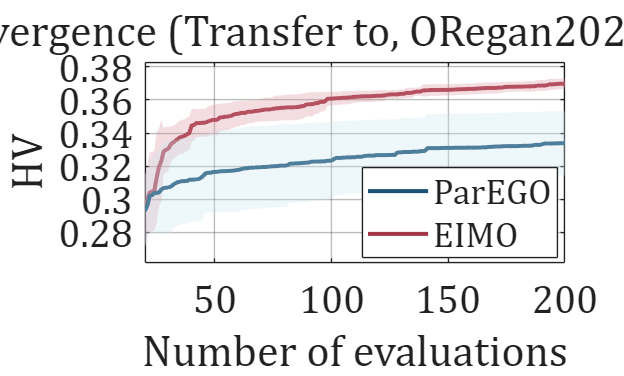

  ✅ ORegan2022 模型收敛图已保存：result_exp6\Convergence_ORegan2022.png


正在绘制 Ecker2015 模型的收敛图...


20
21
22
23
24
25
26
27
28
29
30
31
32
33
34
35
36
37
38
39
40
41
42
43
44
45
46
47
48
49
50
51
52
53
54
55
56
57
58
59
60
61
62
63
64
65
66
67
68
69
70
71
72
73
74
75
76
77
78
79
80
81
82
83
84
85
86
87
88
89
90
91
92
93
94
95
96
97
98
99
100
101
102
103
104
105
106
107
108
109
110
111
112
113
114
115
116
117
118
119
120
121
122
123
124
125
126
127
128
129
130
131
132
133
134
135
136
137
138
139
140
141
142
143
144
145
146
147
148
149
150
151
152
153
154
155
156
157
158
159
160
161
162
163
164
165
166
167
168
169
170
171
172
173
174
175
176
177
178
179
180
181
182
183
184
185
186
187
188
189
190
191
192
193
194
195
196
197
198
199
200


20
21
22
23
24
25
26
27
28
29
30
31
32
33
34
35
36
37
38
39
40
41
42
43
44
45
46
47
48
49
50
51
52
53
54
55
56
57
58
59
60
61
62
63
64
65
66
67
68
69
70
71
72
73
74
75
76
77
78
79
80
81
82
83
84
85
86
87
88
89
90
91
92
93
94
95
96
97
98
99
100
101
102
103
104
105
106
107
108
109
110
111
112
113
114
115
116
117
118
119
120
121
122
123
124
125
126
127
128
129
130
131
132
133
134
135
136
137
138
139
140
141
142
143
144
145
146
147
148
149
150
151
152
153
154
155
156
157
158
159
160
161
162
163
164
165
166
167
168
169
170
171
172
173
174
175
176
177
178
179
180
181
182
183
184
185
186
187
188
189
190
191
192
193
194
195
196
197
198
199
200


20
21
22
23
24
25
26
27
28
29
30
31
32
33
34
35
36
37
38
39
40
41
42
43
44
45
46
47
48
49
50
51
52
53
54
55
56
57
58
59
60
61
62
63
64
65
66
67
68
69
70
71
72
73
74
75
76
77
78
79
80
81
82
83
84
85
86
87
88
89
90
91
92
93
94
95
96
97
98
99
100
101
102
103
104
105
106
107
108
109
110
111
112
113
114
115
116
117
118
119
120
121
122
123
124
125
126
127
128
129
130
131
132
133
134
135
136
137
138
139
140
141
142
143
144
145
146
147
148
149
150
151
152
153
154
155
156
157
158
159
160
161
162
163
164
165
166
167
168
169
170
171
172
173
174
175
176
177
178
179
180
181
182
183
184
185
186
187
188
189
190
191
192
193
194
195
196
197
198
199
200


20
21
22
23
24
25
26
27
28
29
30
31
32
33
34
35
36
37
38
39
40
41
42
43
44
45
46
47
48
49
50
51
52
53
54
55
56
57
58
59
60
61
62
63
64
65
66
67
68
69
70
71
72
73
74
75
76
77
78
79
80
81
82
83
84
85
86
87
88
89
90
91
92
93
94
95
96
97
98
99
100
101
102
103
104
105
106
107
108
109
110
111
112
113
114
115
116
117
118
119
120
121
122
123
124
125
126
127
128
129
130
131
132
133
134
135
136
137
138
139
140
141
142
143
144
145
146
147
148
149
150
151
152
153
154
155
156
157
158
159
160
161
162
163
164
165
166
167
168
169
170
171
172
173
174
175
176
177
178
179
180
181
182
183
184
185
186
187
188
189
190
191
192
193
194
195
196
197
198
199
200


20
21
22
23
24
25
26
27
28
29
30
31
32
33
34
35
36
37
38
39
40
41
42
43
44
45
46
47
48
49
50
51
52
53
54
55
56
57
58
59
60
61
62
63
64
65
66
67
68
69
70
71
72
73
74
75
76
77
78
79
80
81
82
83
84
85
86
87
88
89
90
91
92
93
94
95
96
97
98
99
100
101
102
103
104
105
106
107
108
109
110
111
112
113
114
115
116
117
118
119
120
121
122
123
124
125
126
127
128
129
130
131
132
133
134
135
136
137
138
139
140
141
142
143
144
145
146
147
148
149
150
151
152
153
154
155
156
157
158
159
160
161
162
163
164
165
166
167
168
169
170
171
172
173
174
175
176
177
178
179
180
181
182
183
184
185
186
187
188
189
190
191
192
193
194
195
196
197
198
199
200


20
21
22
23
24
25
26
27
28
29
30
31
32
33
34
35
36
37
38
39
40
41
42
43
44
45
46
47
48
49
50
51
52
53
54
55
56
57
58
59
60
61
62
63
64
65
66
67
68
69
70
71
72
73
74
75
76
77
78
79
80
81
82
83
84
85
86
87
88
89
90
91
92
93
94
95
96
97
98
99
100
101
102
103
104
105
106
107
108
109
110
111
112
113
114
115
116
117
118
119
120
121
122
123
124
125
126
127
128
129
130
131
132
133
134
135
136
137
138
139
140
141
142
143
144
145
146
147
148
149
150
151
152
153
154
155
156
157
158
159
160
161
162
163
164
165
166
167
168
169
170
171
172
173
174
175
176
177
178
179
180
181
182
183
184
185
186
187
188
189
190
191
192
193
194
195
196
197
198
199
200


20
21
22
23
24
25
26
27
28
29
30
31
32
33
34
35
36
37
38
39
40
41
42
43
44
45
46
47
48
49
50
51
52
53
54
55
56
57
58
59
60
61
62
63
64
65
66
67
68
69
70
71
72
73
74
75
76
77
78
79
80
81
82
83
84
85
86
87
88
89
90
91
92
93
94
95
96
97
98
99
100
101
102
103
104
105
106
107
108
109
110
111
112
113
114
115
116
117
118
119
120
121
122
123
124
125
126
127
128
129
130
131
132
133
134
135
136
137
138
139
140
141
142
143
144
145
146
147
148
149
150
151
152
153
154
155
156
157
158
159
160
161
162
163
164
165
166
167
168
169
170
171
172
173
174
175
176
177
178
179
180
181
182
183
184
185
186
187
188
189
190
191
192
193
194
195
196
197
198
199
200


20
21
22
23
24
25
26
27
28
29
30
31
32
33
34
35
36
37
38
39
40
41
42
43
44
45
46
47
48
49
50
51
52
53
54
55
56
57
58
59
60
61
62
63
64
65
66
67
68
69
70
71
72
73
74
75
76
77
78
79
80
81
82
83
84
85
86
87
88
89
90
91
92
93
94
95
96
97
98
99
100
101
102
103
104
105
106
107
108
109
110
111
112
113
114
115
116
117
118
119
120
121
122
123
124
125
126
127
128
129
130
131
132
133
134
135
136
137
138
139
140
141
142
143
144
145
146
147
148
149
150
151
152
153
154
155
156
157
158
159
160
161
162
163
164
165
166
167
168
169
170
171
172
173
174
175
176
177
178
179
180
181
182
183
184
185
186
187
188
189
190
191
192
193
194
195
196
197
198
199
200


20
21
22
23
24
25
26
27
28
29
30
31
32
33
34
35
36
37
38
39
40
41
42
43
44
45
46
47
48
49
50
51
52
53
54
55
56
57
58
59
60
61
62
63
64
65
66
67
68
69
70
71
72
73
74
75
76
77
78
79
80
81
82
83
84
85
86
87
88
89
90
91
92
93
94
95
96
97
98
99
100
101
102
103
104
105
106
107
108
109
110
111
112
113
114
115
116
117
118
119
120
121
122
123
124
125
126
127
128
129
130
131
132
133
134
135
136
137
138
139
140
141
142
143
144
145
146
147
148
149
150
151
152
153
154
155
156
157
158
159
160
161
162
163
164
165
166
167
168
169
170
171
172
173
174
175
176
177
178
179
180
181
182
183
184
185
186
187
188
189
190
191
192
193
194
195
196
197
198
199
200


20
21
22
23
24
25
26
27
28
29
30
31
32
33
34
35
36
37
38
39
40
41
42
43
44
45
46
47
48
49
50
51
52
53
54
55
56
57
58
59
60
61
62
63
64
65
66
67
68
69
70
71
72
73
74
75
76
77
78
79
80
81
82
83
84
85
86
87
88
89
90
91
92
93
94
95
96
97
98
99
100
101
102
103
104
105
106
107
108
109
110
111
112
113
114
115
116
117
118
119
120
121
122
123
124
125
126
127
128
129
130
131
132
133
134
135
136
137
138
139
140
141
142
143
144
145
146
147
148
149
150
151
152
153
154
155
156
157
158
159
160
161
162
163
164
165
166
167
168
169
170
171
172
173
174
175
176
177
178
179
180
181
182
183
184
185
186
187
188
189
190
191
192
193
194
195
196
197
198
199
200


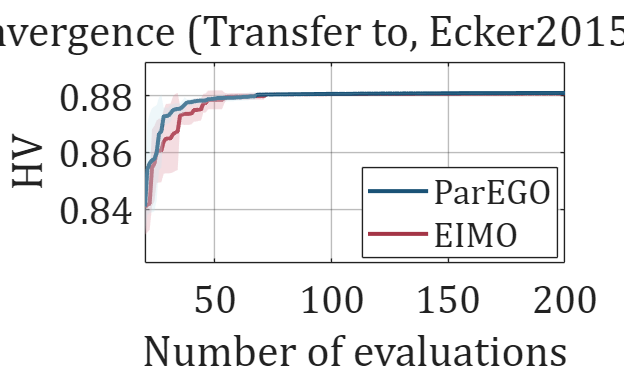

  ✅ Ecker2015 模型收敛图已保存：result_exp6\Convergence_Ecker2015.png


clc;clear;close all;

% ===================== 基础配置（沿用你的风格） =====================
% 颜色设置（保留你的配色方案）
c = ['#A43546';'#1A5276';'#963CC2';'#4E9E35';'#AAAC4D';'#26F1F1'];
cc = [[220,144,156]/255;...
    [199,229,237]/255;[200,157,222]/255;...
    [233,255,233]/255;[252,255,228]/255;[216,255,255]/255];
facealpha = 0.3;
lw = 2;

% 实验配置
n_runs = 5;                       % 5次重复实验
model_types = ["ORegan2022", "Ecker2015"];  % 两个电池模型
save_path = 'result_exp6/';       % 数据路径
REFER_UP = [8000,8,1.5];          % HV计算上参考点（沿用你的配置）
REFER_LOW = [0,0,0];         % HV计算下参考点
eval_range = 20:1:200;           % 评估次数范围
hv_length = length(eval_range);  % 181个数据点

% ===================== 循环绘制每个电池模型的收敛图 =====================
for model_idx = 1:length(model_types)
    model_type = model_types(model_idx);
    fprintf('正在绘制 %s 模型的收敛图...\n', model_type);
    
    % ---------- 1. 预分配内存并加载数据 ----------
    HVEEI = zeros(n_runs, hv_length);  % EIMO(EEI)的HV值
    HVPAR = zeros(n_runs, hv_length);   % ParEGO的HV值
    
    for i = 1:n_runs
        % 加载EEI(EIMO)数据
        eei_file = fullfile(save_path, sprintf("EEI_DATA_%s_200_%d.mat", model_type, i));
        if exist(eei_file, 'file')
            load(eei_file);
            % 计算HV值（适配你的cal_hv函数）
            HV1 = cal_hv(EEI_DATA, REFER_UP, REFER_LOW);
            HVEEI(i,:) = HV1(1,1:hv_length);  % 取前181个点
        else
            warning('EEI数据文件不存在：%s', eei_file);
            HVEEI(i,:) = NaN(1, hv_length);
        end
        
        % 加载ParEGO数据
        par_file = fullfile(save_path, sprintf("ParEGO_DATA_%s_200_%d.mat", model_type, i));
        if exist(par_file, 'file')
            load(par_file);
            % 计算HV值（适配你的cal_hv函数）
            HV2 = cal_hv(ParEGO_DATA, REFER_UP, REFER_LOW);
            HVPAR(i,:) = HV2(1,1:hv_length);  % 取前181个点
        else
            warning('ParEGO数据文件不存在：%s', par_file);
            HVPAR(i,:) = NaN(1, hv_length);
        end
    end
    
    % ---------- 2. 计算均值和标准差（剔除NaN值） ----------
    EEI_mean = nanmean(HVEEI, 1);  % 忽略NaN求均值
    EEI_std = nanstd(HVEEI, 0, 1); % 忽略NaN求标准差
    PAR_mean = nanmean(HVPAR, 1);
    PAR_std = nanstd(HVPAR, 0, 1);
    
    % 保存HV数据（可选）
    save(fullfile(save_path, sprintf('HV_%s.mat', model_type)), ...
         'EEI_mean','EEI_std','PAR_mean','PAR_std');
    
    % ---------- 3. 绘制收敛图（完全沿用你的风格） ----------
    figure(model_idx);
    clf; hold on; grid on; box on;
    it = eval_range;  % 20-200评估次数
    
    % 绘制EIMO(EEI)曲线 + 误差带
    p1 = plot(it,EEI_mean,'-','LineWidth',lw,'color',c(1,:),'MarkerSize',1);
    y1 = EEI_mean + EEI_std;
    y2 = EEI_mean - EEI_std;
    h = fill([it,fliplr(it)],[y1,fliplr(y2)],cc(1,:));
    set(h,'edgealpha',0,'facealpha',facealpha);
    
    % 绘制ParEGO曲线 + 误差带
    p2 = plot(it,PAR_mean,'-','LineWidth',lw,'color',c(2,:),'MarkerSize',1);
    y1 = PAR_mean + PAR_std;
    y2 = PAR_mean - PAR_std;
    h = fill([it,fliplr(it)],[y1,fliplr(y2)],cc(2,:));
    set(h,'edgealpha',0,'facealpha',facealpha);
    
    % ---------- 4. 图形格式设置（与你的代码完全一致） ----------
    xlim([20,200]);
    % 自适应纵坐标（避免硬编码，兼容不同模型）
    all_hv_data = [EEI_mean, PAR_mean, EEI_mean+EEI_std, EEI_mean-EEI_std, PAR_mean+PAR_std, PAR_mean-PAR_std];
    y_min = nanmin(all_hv_data) - 0.01;
    y_max = nanmax(all_hv_data) + 0.01;
    ylim([y_min, y_max]);
    
    % 图例（沿用你的顺序）
    legend([p2,p1],'ParEGO','EIMO','Location','best');
    
    % 坐标轴标签（与你的风格一致）
    xlabel('Number of evaluations','FontName','Cambria','FontSize',20);
    ylabel('HV','FontName','Cambria','FontSize',20);
    title(sprintf('Convergence (Transfer to, %s Model)', model_type),...
          'FontName','Cambria','FontSize',22);
    
    % 字体设置
    set(gca,'fontname','Cambria','fontsize',20);
    set(gca,'GridAlpha',0.3);  % 网格透明度优化
    
    % ---------- 5. 保存高清图片 ----------
    save_name = fullfile(save_path, sprintf('Convergence_%s.png', model_type));
    print(gcf, save_name, '-dpng', '-r300');  % 300dpi高清保存
    fprintf('  ✅ %s 模型收敛图已保存：%s\n', model_type, save_name);
end


fprintf('\n🎉 所有收敛图绘制完成！\n');


🎉 所有收敛图绘制完成！


正在绘制 ORegan2022 模型的收敛图...


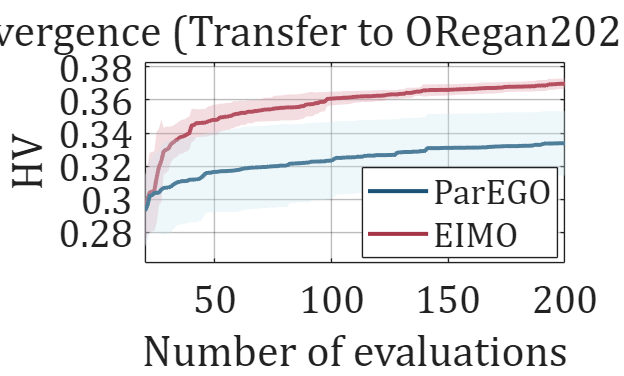

  ✅ ORegan2022 模型收敛图已保存：result_exp6\Convergence_ORegan2022.png


正在绘制 Ecker2015 模型的收敛图...


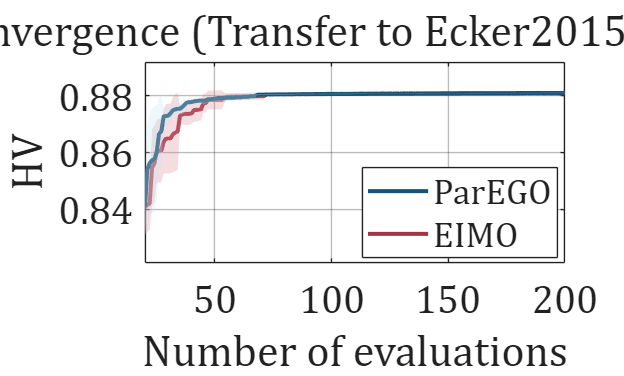

  ✅ Ecker2015 模型收敛图已保存：result_exp6\Convergence_Ecker2015.png


clc;clear;close all;

% ===================== 基础配置（完全沿用你的风格） =====================
% 颜色设置（保留你的配色方案）
c = ['#A43546';'#1A5276';'#963CC2';'#4E9E35';'#AAAC4D';'#26F1F1'];
cc = [[220,144,156]/255;...
    [199,229,237]/255;[200,157,222]/255;...
    [233,255,233]/255;[252,255,228]/255;[216,255,255]/255];
facealpha = 0.3;
lw = 2;

% 实验配置
model_types = ["ORegan2022", "Ecker2015"];  % 两个电池模型
save_path = 'result_exp6/';       % 数据路径（HV_*.mat所在路径）
eval_range = 20:1:200;           % 评估次数范围
hv_length = length(eval_range);  % 181个数据点

% ===================== 循环绘制每个电池模型的收敛图 =====================
for model_idx = 1:length(model_types)
    model_type = model_types(model_idx);
    fprintf('正在绘制 %s 模型的收敛图...\n', model_type);
    
    % ---------- 1. 直接加载已保存的HV统计文件 ----------
    hv_file = fullfile(save_path, sprintf('HV_%s.mat', model_type));
    if ~exist(hv_file, 'file')
        error('HV统计文件不存在：%s，请先运行原始脚本生成该文件', hv_file);
    end
    load(hv_file);  % 加载：EEI_mean, EEI_std, PAR_mean, PAR_std
    
    % ---------- 2. 绘制收敛图（完全沿用你的风格） ----------
    figure(model_idx);
    clf; hold on; grid on; box on;
    it = eval_range;  % 20-200评估次数
    
    % 绘制EIMO(EEI)曲线 + 误差带
    p1 = plot(it,EEI_mean,'-','LineWidth',lw,'color',c(1,:),'MarkerSize',1);
    y1 = EEI_mean + EEI_std;
    y2 = EEI_mean - EEI_std;
    h = fill([it,fliplr(it)],[y1,fliplr(y2)],cc(1,:));
    set(h,'edgealpha',0,'facealpha',facealpha);
    
    % 绘制ParEGO曲线 + 误差带
    p2 = plot(it,PAR_mean,'-','LineWidth',lw,'color',c(2,:),'MarkerSize',1);
    y1 = PAR_mean + PAR_std;
    y2 = PAR_mean - PAR_std;
    h = fill([it,fliplr(it)],[y1,fliplr(y2)],cc(2,:));
    set(h,'edgealpha',0,'facealpha',facealpha);
    
    % ---------- 3. 图形格式设置（与你的代码完全一致） ----------
    xlim([20,200]);
    % 自适应纵坐标（避免硬编码，兼容不同模型）
    all_hv_data = [EEI_mean, PAR_mean, EEI_mean+EEI_std, EEI_mean-EEI_std, PAR_mean+PAR_std, PAR_mean-PAR_std];
    y_min = nanmin(all_hv_data) - 0.01;
    y_max = nanmax(all_hv_data) + 0.01;
    ylim([y_min, y_max]);
    
    % 图例（沿用你的顺序）
    legend([p2,p1],'ParEGO','EIMO','Location','best');
    
    % 坐标轴标签（与你的风格一致）
    xlabel('Number of evaluations','FontName','Cambria','FontSize',20);
    ylabel('HV','FontName','Cambria','FontSize',20);
    title(sprintf('Convergence (Transfer to %s Model)', model_type),...
          'FontName','Cambria','FontSize',22);
    
    % 字体设置
    set(gca,'fontname','Cambria','fontsize',20);
    set(gca,'GridAlpha',0.3);  % 网格透明度优化
    
    % ---------- 4. 保存高清图片 ----------
    save_name = fullfile(save_path, sprintf('Convergence_%s.png', model_type));
    print(gcf, save_name, '-dpng', '-r300');  % 300dpi高清保存
    fprintf('  ✅ %s 模型收敛图已保存：%s\n', model_type, save_name);
end


fprintf('\n🎉 所有收敛图绘制完成！\n');


🎉 所有收敛图绘制完成！
